# Jリーグのクラブ数を集計する

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;

csvファイルをtable形式で読み込む

tbl=readtable('../data/JLeagueResults.xlsx')

tbl = 22899×15 table
    MatchID    Year    Category        Date           KickoffTime          HomeJ          HomeE           AwayJ          AwayE         HomeGoals    AwayGoals    HomePKs    AwayPKs      Stadium      Attendance
    _______    ____    _________    __________    ___________________    _________    ______________    _________    ______________    _________    _________    _______    _______    ___________    __________

       1       1992    {'ＹＮＣ'}    1992/09/05    1992/09/05 15:00:00    {'鹿島' }    {'kashima'   }    {'横浜Ｆ'}     {'yokohamaf' }        4            2          NaN        NaN      {'笠松'   }       5226   
       3       1992    {'ＹＮＣ'}    1992/09/05    1992/09/05 15:30:00    {'名古屋'}    {'nagoya'    }    {'清水' }     {'shimizu'   }        3            0          NaN        NaN      {'瑞穂球'  }       8029   
       4       1992    {'ＹＮＣ'}    1992/09/05    1992/09/05 18:02:00    {'浦和' }    {'urawa'     }    {'市原' }     {'chiba'     }        2            3        

チーム名の文字列を抽出する

teamNameStrs=unique([tbl.HomeE;tbl.AwayE])

teamNameStrs = 65×1 の cell 配列
    {'J-22'      }
    {'akita'     }
    {'chiba'     }
    {'cosaka'    }
    {'cosaka_u23'}
    {'ehime'     }
    {'fosaka'    }
    {'ftokyo'    }
    {'ftokyo_u23'}
    {'fujieda'   }
    {'fukuoka'   }
    {'fukushima' }
    {'gifu'      }
    {'gosaka'    }
    {'gosaka_u23'}
    {'hachinohe' }
    {'hiroshima' }
    {'imabari'   }
    {'iwaki'     }
    {'iwata'     }
    {'kagoshima' }
    {'kanazawa'  }
    {'kashima'   }
    {'kashiwa'   }
    {'kawasakif' }
    {'kitakyushu'}
    {'kobe'      }
    {'kofu'      }
    {'kumamoto'  }
    {'kusatsu'   }


それぞれのチーム名の列をカテゴリ型の変数に変換する

tbl.HomeE=categorical(tbl.HomeE);
tbl.AwayE=categorical(tbl.AwayE);

大会カテゴリ名もカテゴリ型の変数に変換する

tbl.Category=categorical(tbl.Category);

年(シーズン)の範囲を抽出する

yearVals=unique(tbl.Year)

yearVals =         1992
        1993
        1994
        1995
        1996
        1997
        1998
        1999
        2000
        2001


年毎に各大会カテゴリに参戦しているチーム数を集計する

plotData=[];
for yearVal=yearVals'
    ind = tbl.Year==yearVal;
    tbl_tmp=tbl(ind,:);
    % J1
    ind = ismember(tbl_tmp.Category, ...
        {'Ｊ１','Ｊ１ サントリー','Ｊ１ １ｓｔ','Ｊ１ ２ｎｄ',...
        'Ｊ１ ＮＩＣＯＳ'});
    tmpTeamNames_J1=unique([tbl_tmp.HomeE(ind);tbl_tmp.AwayE(ind)]);

    % J2
    ind = ismember(tbl_tmp.Category,{'Ｊ２'});
    tmpTeamNames_J2=unique([tbl_tmp.HomeE(ind);tbl_tmp.AwayE(ind)]);
    
    % J3
    ind = ismember(tbl_tmp.Category,{'Ｊ３'});
    tmpTeamNames_J3=unique([tbl_tmp.HomeE(ind);tbl_tmp.AwayE(ind)]);
    
    plotData=[plotData; ...
        size(tmpTeamNames_J1,1) ...
        size(tmpTeamNames_J2,1) ...
        size(tmpTeamNames_J3,1) ...
        ];
end

積み上げ(stacked)帯グラフを作る

figure;
bar(yearVals, plotData,'stacked');

格子(grid)を追加する

grid on;

現在のグラフ(軸．gca=get current axis)の設定を変更する

set(gca,'fontname','メイリオ');

各軸の説明(label)を設定する

xlabel('年');
ylabel('クラブ数');

凡例(legend)を設定する

legend({'J1','J2','J3'},'location','northoutside', ...
    'Orientation',"horizontal")

題名(title)を設定する

title('Jリーグクラブ数')

図をpdf形式で出力する

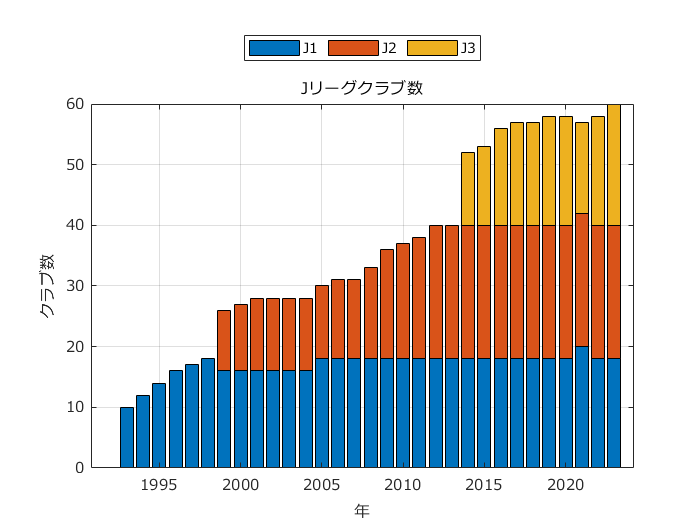

exportgraphics(gcf, 'fig_numOfClubsInJLeague.pdf');